# Sessió 9

**Yaiza Cano, Narcís Terrado**

## 1.1. Processat + Segmentació per binarització per Otsu

La imatge amb la que treballarem en aquest primer apartat de la pràctica serà *arros.tif. *Per segmentar-la automàticament per binarització per Otsu, primerament probarem a fer-ho directament convertint la imatge a una imatge binària.

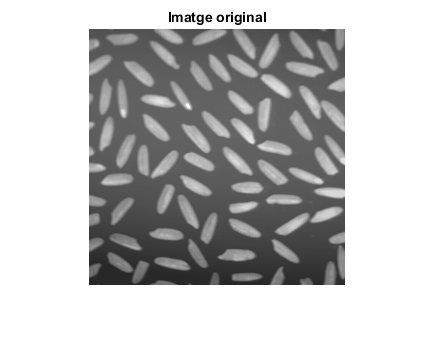

orig = imread("arros.tif");
imshow(orig), title("Imatge original");

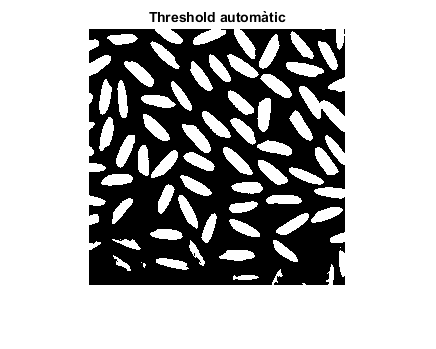


%segmentació per binarització per Otsu
bw = im2bw(orig, graythresh(orig)); 
figure, imshow(bw), title("Threshold automàtic");

Com podem veure, en aquesta binarització perdem grans. Això és degut a que la il·luminació no és gens homogènia i els detectors automàtics de llindar no detecten correctament.

Per arreglar aquest problema, hem de filtrar morfològicament la imatge separant la il·luminació que hi ha de fons per a posteriorment restar-se-la.

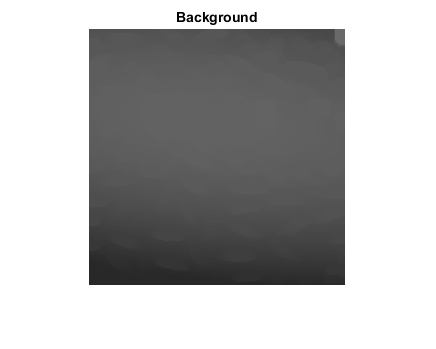

%filtre morfològic
bg = imopen(orig, strel('disk',10));
figure, imshow(bg), title("Background");

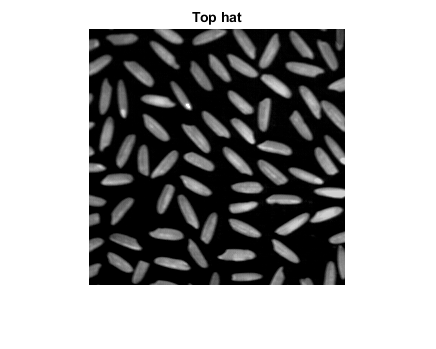


%mostrem el background com si fos una superfície
figure, surf(bg); title("Background com a superfície");

%li restem el background a la imatge.
y = imsubtract(orig, bg);
figure, imshow(y, []), title("Top hat");

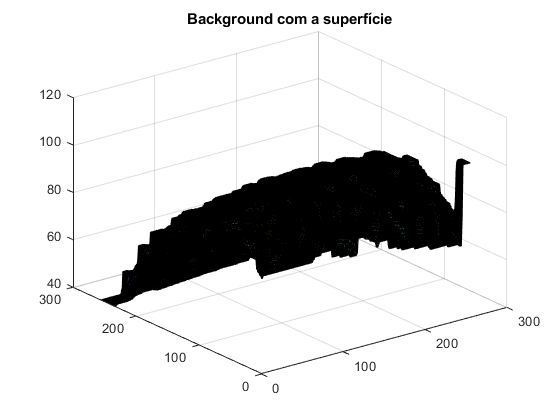

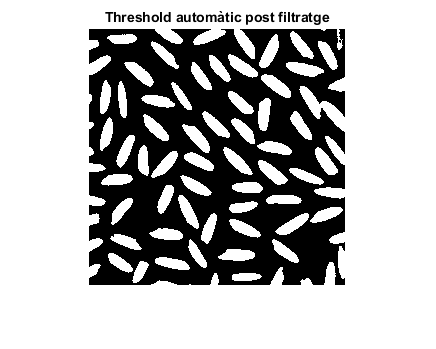


%tornem a segmentar la imatge per Otsu
bw = im2bw(y, graythresh(y));
figure, imshow(bw), title("Threshold automàtic post filtratge");

Ara podem comprobar que amb la resta d'imatges aconseguim una imatge sense il·luminació *Top hat, *on es distingueixen, ara sí, perfectament tots els grans i amb la qual podem obtenir una bona binartizació per Otsu.

## 1.2. Etiquetat + Descripció de regions

Un cop tenim la imatge binaritzada correctament, etiquetem la imatge amb motiu d'obtenim descriptors de les regions els quals computen totes les mesures de forma possibles.

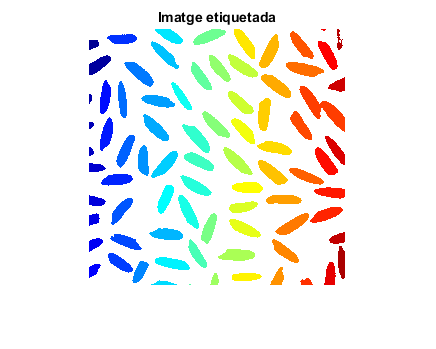

%etiquetem la imatge segmentada
[eti, num] = bwlabel(bw,4);
figure, imshow(label2rgb(eti)), title("Imatge etiquetada");


%comptem ara el nombre d'objectes a la imatge
num;

%obtenim descriptors de les regions
Dades = regionprops(eti,"all");

## 1.3. Exercici

Abans de representar les propietats descrites a *regionprops, *hem de modificar la imatge *bw*, ja que en la que tenim ara apareixen grans d'arròs en contacte que el computador interpreta que són 1 sol i grans que toquen les vores. Tots aquests grans falsegen els resultats i per tant, s'han d'eliminar de la imatge.

#### Separació de grans en contacte amb altres

Per dur a terme aquest exercici, hem seguit el tutorial de *watershed segmentation* d'*Steve Eddins*, link: [https://blogs.mathworks.com/steve/2013/11/19/watershed-transform-question-from-tech-support/.](https://blogs.mathworks.com/steve/2013/11/19/watershed-transform-question-from-tech-support/.)

- Computem la transformació de la *distància*. 

- Computem la transformació per *watershed*.

- Utilitzem les línies blanques obtingudes pel *watershed* (Ld == 0) per segmentar la imatge binària.

- Cobrim els mínims locals creats per la sobresegmentació anterior i modifiquem la transformació de la *distància* per a obtenir els resultats que desitgem.

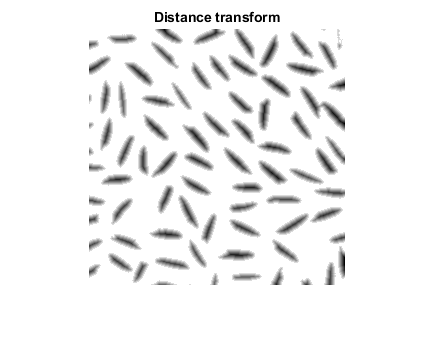

D = -bwdist(~bw);
figure, imshow(D,[]), title("Distance transform");

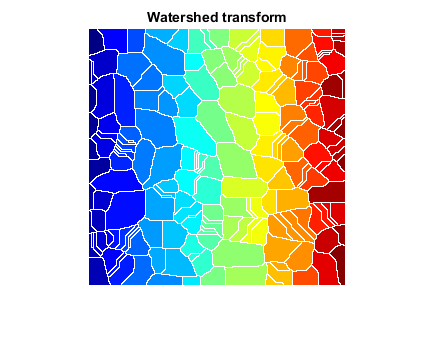


Ld = watershed(D);
figure, imshow(label2rgb(Ld)), title("Watershed transform")

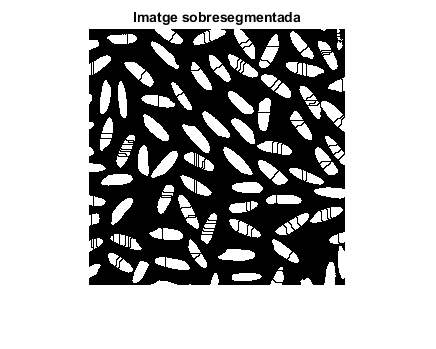


bw2 = bw;
bw2(Ld == 0) = 0;
figure, imshow(bw2), title("Imatge sobresegmentada")

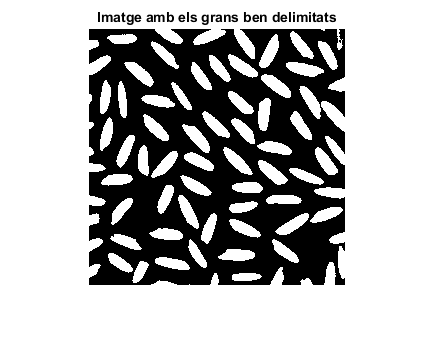


mask = imextendedmin(D,2);
D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
bw3 = bw;
bw3(Ld2 == 0) = 0;
figure, imshow(bw3), title("Imatge amb els grans ben delimitats")

#### Eliminació de grans que toquen les vores

Per dur a terme aquest exercici, hem seguit el procediment de la *dilatació condicionada* explicada a la *sessió 4.*

- Creem una imatge que ens servirà com a *marker *la qual serà tota negra menys un petit marc al voltant que serà blanc.

- Creem un *element estructural *amb el que dilatarem el *marker* que després sobreposarem a la imatge.

- Reconstruirem una imatge amb tots aquells grans d'arròs que estan en contacte amb les vores i que ara tenim identificats.

- Restem la imatge anterior a la original.

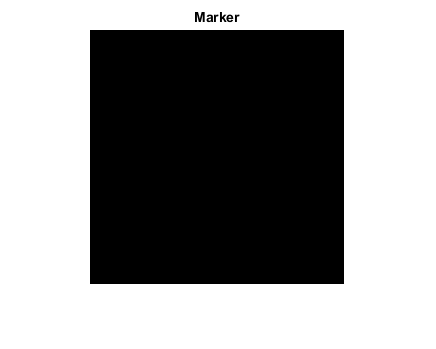

mark = true(256);
mark(2:end-1, 2:end-1) = 0;
figure, imshow(mark), title("Marker");

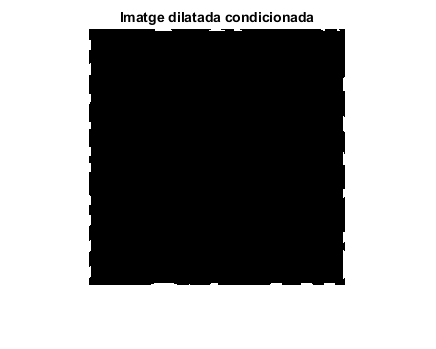


ee = strel('disk',1);
dilc = imdilate(mark,ee) & bw3;
figure, imshow(dilc), title("Imatge dilatada condicionada");

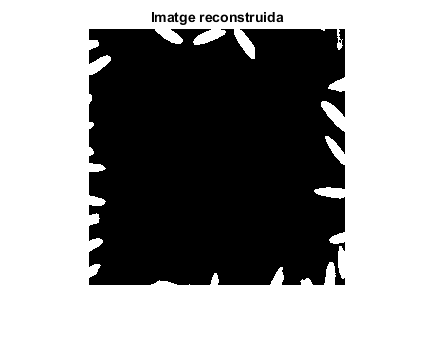


rec = imreconstruct(mark, bw3);
figure, imshow(rec); title("Imatge reconstruida");

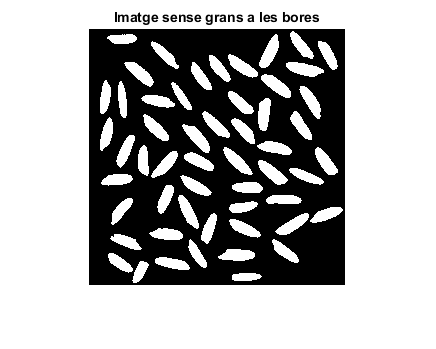


sub = imsubtract(bw3,rec);
figure, imshow(sub,[]), title("Imatge sense grans a les bores")

#### Obtenció i representació de propietats

Un cop etiquetada la imatge, queda decidir quines propietats són les que volem representar per definir la qualitat dels grans d'arròs.

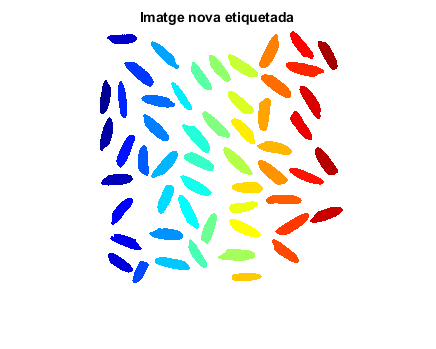

[eti, num] = bwlabel(sub,4);
figure, imshow(label2rgb(eti)), title("Imatge nova etiquetada");

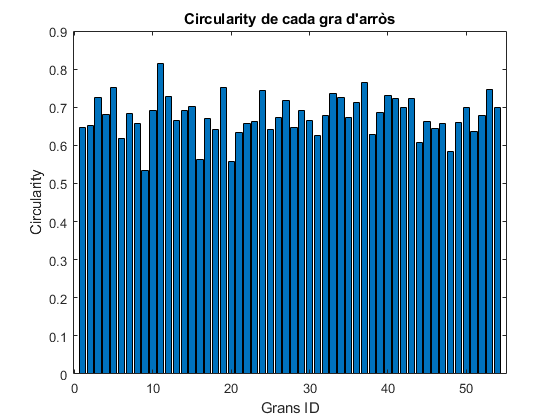


Dades = regionprops(eti,"all");

%HEM DE DECIDIR QUINES PROPIETATS VOLEM PRINTEJAR

%EXEMPLE DE CENTROIDES
s = regionprops(eti,"Centroid");
figure, imshow(sub), title("Centroides")
hold on 
for k = 1 : num 
    plot(s(k).Centroid(1), s(k).Centroid(2), 'm.')
end
hold off

%NUMERACIÓ DELS GRANS PER FER ELS PLOTS
figure, imshow(sub), title("Enumaració dels grans d'arròs")
hold on
    for k = 1 : num
        text(s(k).Centroid(1), s(k).Centroid(2), sprintf('%d', k), 'color', 'r')
    end
hold off

%EXEMPLE FENT CIRCULARITY 
figure,
bar(1:num,[Dades.Circularity]);
title("Circularity de cada gra d'arròs");
ylabel("Circularity");
xlabel("Grans ID");

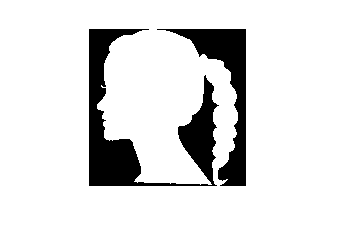


%EXEMPLE DE BOUNDINGBOX 
bb = regionprops(eti,"BoundingBox");
figure, imshow(sub); title("BoundingBox de cada gra d'arròs")
hold on
for k = 1 : num
    rectangle('Position',[bb(k).BoundingBox(1), bb(k).BoundingBox(2), ...
        bb(k).BoundingBox(3), bb(k).BoundingBox(4)], 'EdgeColor','b', "LineWidth",1)
end
hold off

%EXEMPLE RELACIÓ MAJOR AXIS I MINOR AXIS
axis = regionprops(eti, "MajoraxisLength", "MinoraxisLength");
a = [];
for k = 1 : num
    a(k) = axis(k).MajorAxisLength / axis(k).MinorAxisLength;
end
figure
bar(1:num, [a]); title("Relació entre axis");
ylabel("Major/Minor AxisLength");
xlabel("Grans ID");

## 2. Codis de cadena

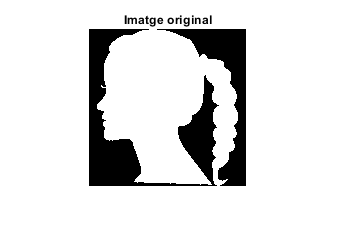

im = imread('head.png');
im = imresize(im,1/4);
imshow(im), title("Imatge original");

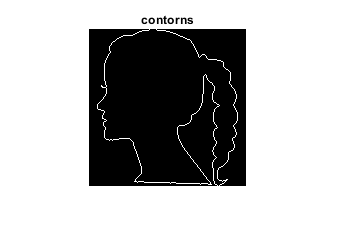


%obtenim el contorn
ero = imerode(im, strel('disk',1));
cont = xor(ero,im);
figure, imshow(cont), title("contorns");

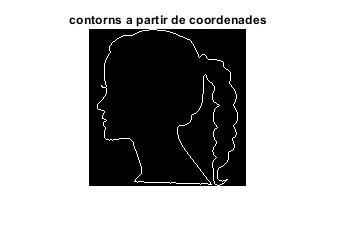


%obtenim les coordenades del contorn
[fila, col] = find(im, 1); %busquem el primer píxel
B = bwtraceboundary(im, [fila, col], 'E'); %direcció est a l'atzar
%B conté les coordenades

%Ho comprovem mostrant el resultat
aux = zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2))) = 1;
figure, imshow(aux), title("contorns a partir de coordenades")

## 2.1. Exercici

Trobar els codis de cadena incrementals a partir de B.

%% NI PUTES

## 3. Descriptors de Fourier

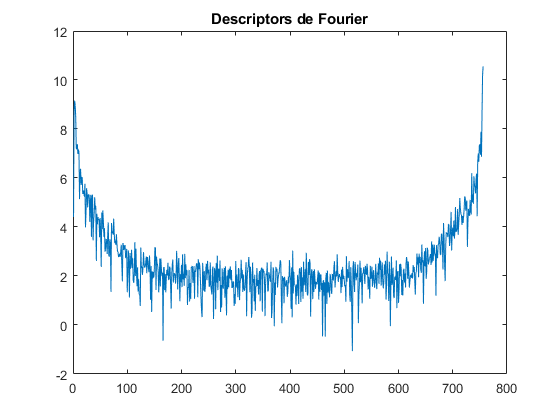

%centrem coordenades
mig = mean(B);
B(:,1) = B(:,1) - mig(1);
B(:,2) = B(:,2) - mig(2);

%convertim les coordenades a complexes
s = B(:,1) + 1i*B(:,2);

%cal que la dimensió del vector sigui parell
[mida, bobo]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end
%calculem la Fast Fourier Transform
z = fft(s);
%representem l'espectre
% ho displaiem logaritmic perquè sinó no es veu res
figure, plot(log(abs(z))), title("Descriptors de Fourier");

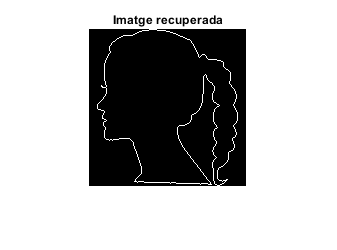


%Recuperem la imatge original per comprovar que el procès és reversible
ss = ifft(z); %Transformada de Fourier inversa
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('Imatge recuperada')

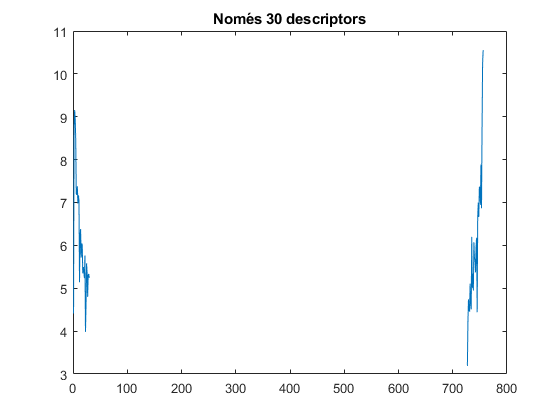


%Reduim la quantitat de descriptors de Fourier
ndesc = 30; %agafem N descriptors
tmp = z;
tmp(ndesc+1:end-ndesc) = 0; %eliminem els del mig perquè es duplica l'espectre
figure, plot(log(abs(tmp))), title("Només 30 descriptors");

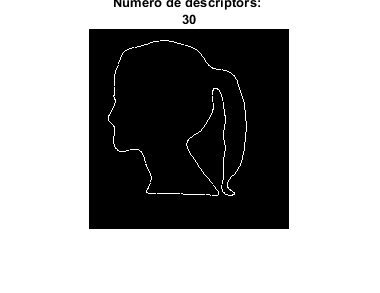


%Tornem al pla imatge a partir de l'espectre modificat
ss2 = ifft(tmp);
%Les coordenades resultants poden sortir del rang de la imatge original
%Creo una imatge més gran per a que les coordenades no se'm surtin de mare
mida = 200;
files = round(real(ss2) + mida/2);
cols = round(imag(ss2) + mida/2);
aux = logical(zeros(mida));
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux); title(["Número de descriptors: ", num2str(ndesc)]);

## 3.1. Exercici

Repetim el procediment descrit en l'apartat anterior però utilitzant quantitats de descriptors diferents per veure quin efecte té això en el detall de la imatge obtinguda.

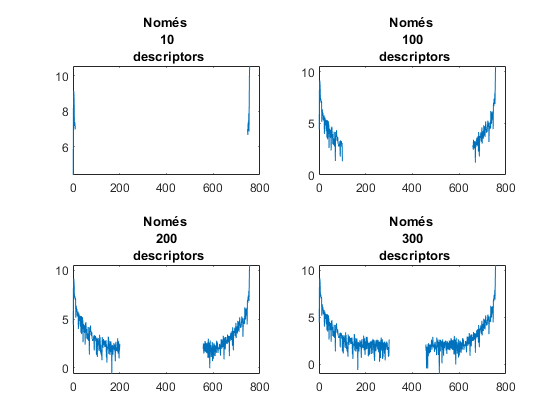

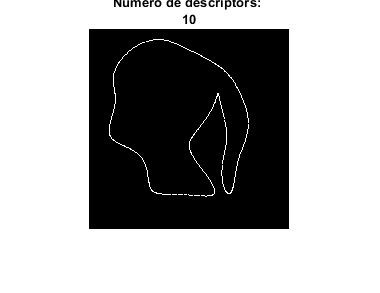

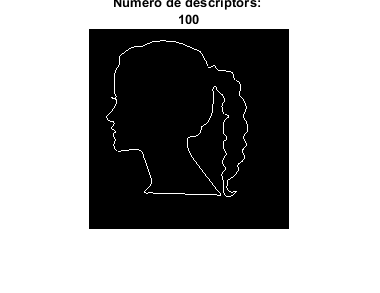

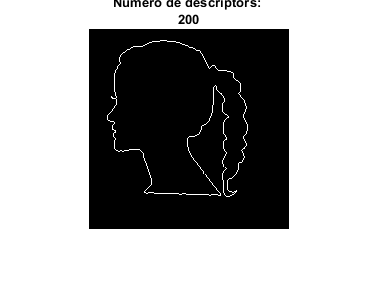

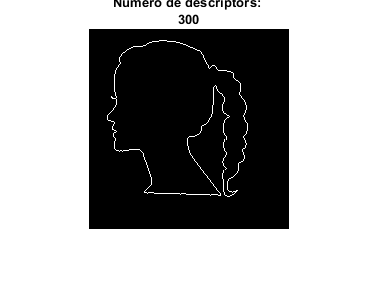

ndesc = [10,100,200,300];
[fn, cn] = size(ndesc);
if mod(cn,2) == 0
    i = cn/2;
    j = i;
else
    i = (cn-1)/2;
    j = i*2+1;
end

tmp = [];
figure,
for k = 1 : cn
    tmp(:, k) = z;
    tmp(ndesc(k)+1:end-ndesc(k),k) = 0;
    subplot(i,j,(k)); plot(log(abs(tmp(:,k)))), title(["Només ", num2str(ndesc(k)), " descriptors"]);
end

pause(0.1); %comentar aquesta línia abans d'exportar a pdf
for k = 1 : cn
    figure, imshow(numDescriptors(200,ifft(tmp(:,k)))); title(["Número de descriptors: ", num2str(ndesc(k))]);    
end